# Plain GNN - Node regression - for optimization design of RC beams - MLOCT 1

This example shows how to train / test use plain GNNs for node regression of optimum amounts of rebar in beams' cross-sections.

This figure below shows the DL architecture and the Loss function of the model.

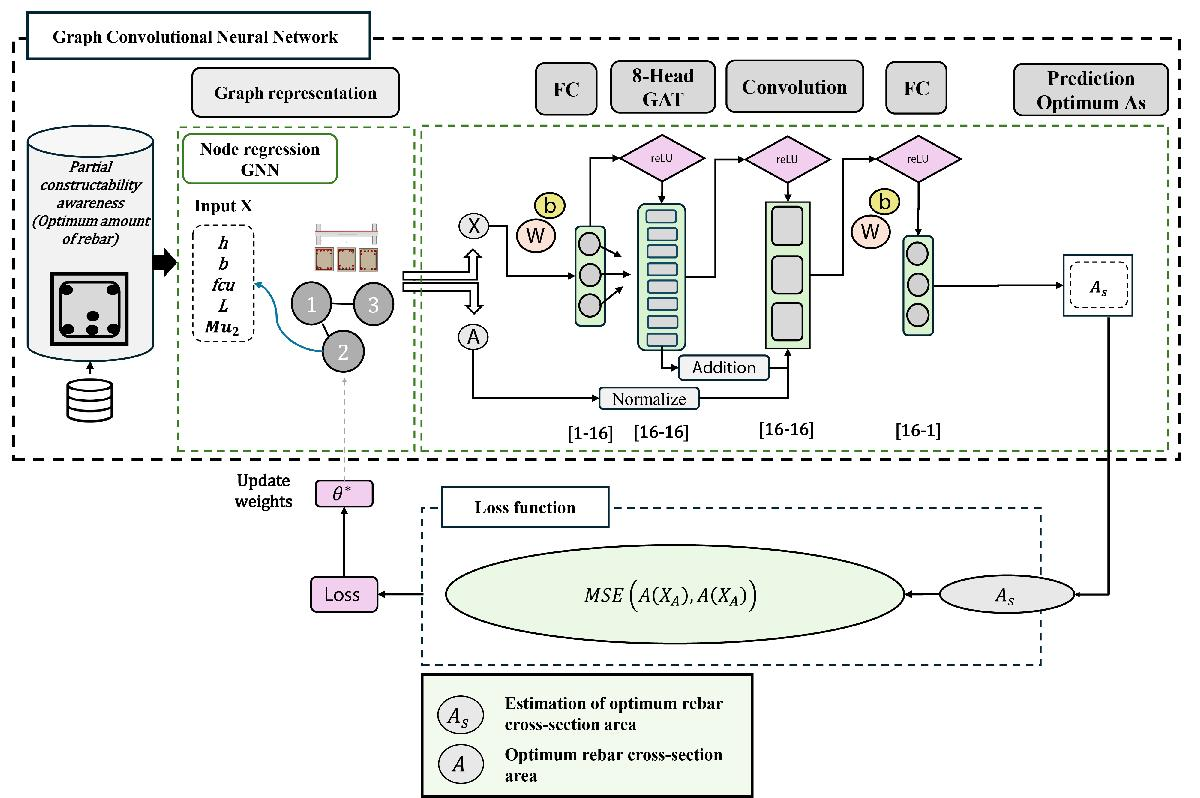

Note: Training this network is a computationally intensive task. To make the example run quicker, this example skips the training step and loads a pretrained network. To instead train the network, set the `doTraining` variable to `true`.

doTraining = false;

## Load Data

Give the path of the folder where the data is stored. Adjust it to your own path.

A=importdata('C:/Users/luizv/OneDrive/CALDRECUST/Software/Package/CALDRECUST-MatLab/MatLab_functions/AI_CALDRECUST_MatLab/Datasets/Data_5LOT_HK_Nb_Db_Simple_4000.xlsx');

DR1=A.data;

n=length(DR1(:,1));


Adjust the variable "subsize" if not all data is required.

subsize=4000;

idxSubData=ceil(rand(subsize,1)*n);

DR=DR1(idxSubData,:);

n=length(DR(:,1));

View the data.

DR

DR = 1.0e+10 *

    0.0000    0.0000    0.0000    0.0000   -0.0081    0.0041   -0.0074    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000   -0.0041    0.0019   -0.0030    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0    0.0000    0.0000    0.0000   

The data is an array of 109 columns. The first 7 columns represent the input features of the nework. b, h, fcu, L, Mur, Mum, Mul. The next two columns are the magnitudes of the distributed loads in N/mm. Then, the rest of columns are the targets (optimum rebar design features, number of rebars and the diameter sizes). Five targets are included for each feature, then, the five constructability values of each optimum design and the rebar weight (in Kg) are included.

[b, h, fcu, L, Mu1, Mu2, Mu3, W1, W2, nb1, nb2, nb3, nb4, nb5, db1, db2, db3, db4, db5, cs1, cs2, cs3, cs4, cs5, ws1, ws2, ws3, ws4, ws5].

Each optimum features (nb1, nb2, ...nb5 and db1, db2, ..., db5) has three components (for each rebar layer). 

This network is trained only for the fifth level of optimum constructability target LOCT1 (or max rebar weight from the Pareto Front from which the data was generated). As shown below: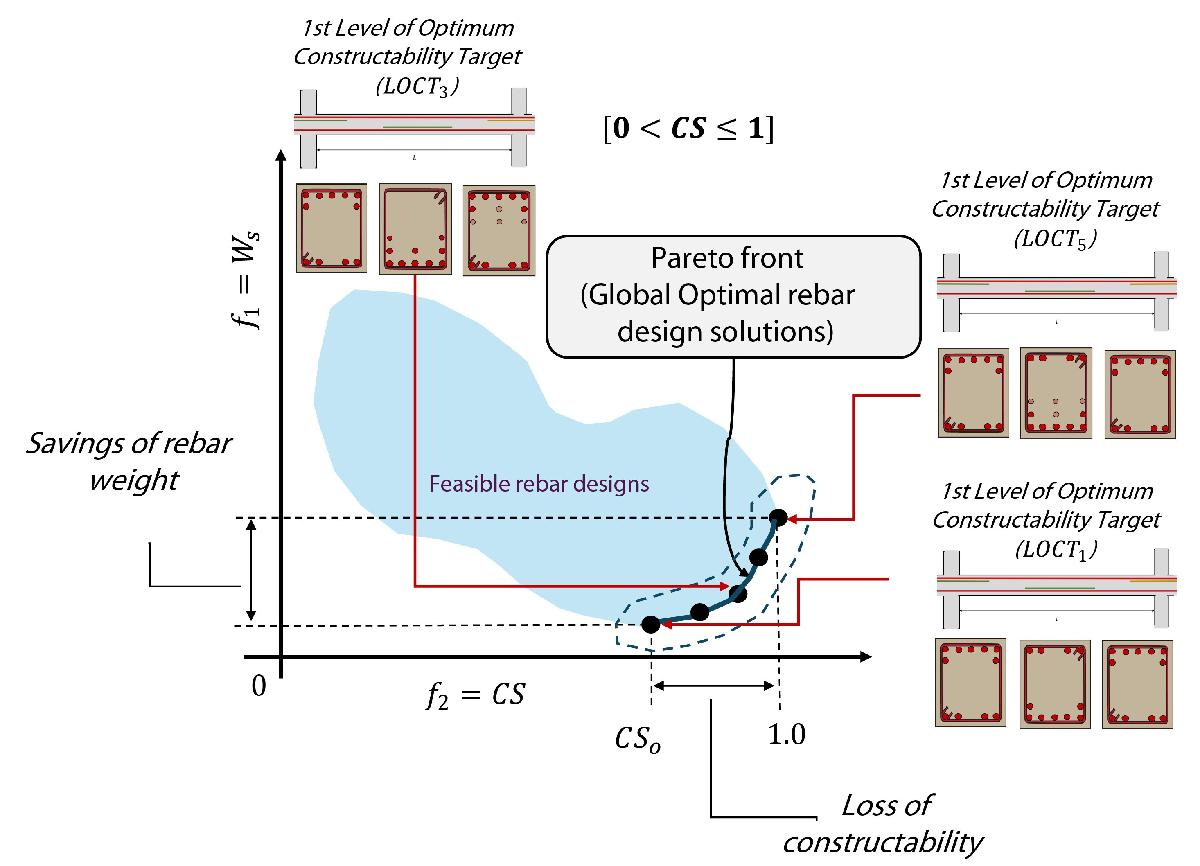

## **Prepare data for training**

**Arrange data in arrays**

numObservations=n;

% Targets
Y1 = [];
for i=1:numObservations
    As9(i,:)=[sum(DR(i,46:48).*DR(i,91:93).^2*pi/4),...
              sum(DR(i,49:51).*DR(i,94:96).^2*pi/4),...
              sum(DR(i,52:54).*DR(i,97:99).^2*pi/4)];


    if sum(As9(i,:)) > 0
        Y1=[Y1;As9(i,:)];
    end
end

n=length(Y1(:,1));
numObservations=ceil(n);

YN1=Y1(:,1); % Node 1: Left
YN2=Y1(:,2); % Node 2: Right
YN3=Y1(:,3); % Node 3: Middle

% Input features
X = [DR(:,1:7)];

 Change variable "targetNorm" to true if normalization of targets is required. Recommended only for Bayesian Optimization of hyperparameters

targetNorm=false

targetNorm = logical
   0


if targetNorm
    muY1=mean(Y1(:,1));
    muY2=mean(Y1(:,2));
    muY3=mean(Y1(:,3));
    
    sigsqY1=var(Y1(:,1),1);
    sigsqY2=var(Y1(:,2),1);
    sigsqY3=var(Y1(:,3),1);
else
    muY1=0;
    muY2=0;
    muY3=0;
    
    sigsqY1=1;
    sigsqY2=1;
    sigsqY3=1;
end
YN1=(YN1-muY1)./sqrt(sigsqY1);
YN2=(YN2-muY2)./sqrt(sigsqY2);
YN3=(YN3-muY3)./sqrt(sigsqY3);

## Define GNN connectivity

### **Node connectivity**

elements=[2 1;
          1 3];

%% Adjacency matrix
numNodesGNN=3;
% Adjancency matrix
adjacency = zeros(numNodesGNN);
for i = 1:size(elements,2)
    % The following logic specifies each node in an element is connected to
    % each other node in that element.
    nodesForElement = elements(:,i);
    for node = nodesForElement
        adjacency(nodesForElement,node) = 1;
    end
end

### **Process input features**

%% Features

features1=[X(:,1),X(:,2),X(:,3),X(:,4),X(:,5)];
features2=[X(:,1),X(:,2),X(:,3),X(:,4),X(:,6)];
features3=[X(:,1),X(:,2),X(:,3),X(:,4),X(:,7)];

DataX1=zeros(numObservations,3,3);
DataX2=zeros(numObservations,3,3);
DataX3=zeros(numObservations,3,3);
DataX4=zeros(numObservations,3,3);
DataX5=zeros(numObservations,3,3);
for i=1:numObservations
    features=[features1(i,:)',features2(i,:)',features3(i,:)'];

    for j=1:numNodesGNN
        DataX1(i,j,j)=features(1,j);
        DataX2(i,j,j)=features(2,j);
        DataX3(i,j,j)=features(3,j);
        DataX4(i,j,j)=features(4,j);
        DataX5(i,j,j)=features(5,j);
    end
end

DataX1 = double(permute(DataX1, [2 3 1]));
DataX2 = double(permute(DataX2, [2 3 1]));
DataX3 = double(permute(DataX3, [2 3 1]));
DataX4 = double(permute(DataX4, [2 3 1]));
DataX5 = double(permute(DataX5, [2 3 1]));

% Process Targets
nodesAb1 = [YN1(:,1),YN2(:,1),YN3(:,1)];

nodesAb1to6=[nodesAb1];

### **Prepare data related to adjacency matrix.**

In this case, all graphs for each beam are the same

adjacency=repmat(adjacency,[1,1,n]);
size(adjacency)

ans =            3           3        4000


### **Partition of data - split for train/validation/test.**

To get a random split, use the `trainingPartitions` function, attached to this example as a supporting file. To access this file, open the example as a live script.

numObservations = size(adjacency,3);
[idxTrain,idxValidation,idxTest] = trainingPartitions(numObservations,[0.7 0.15 0.15]);

% node adjacency data
adjacencyDataTrain = adjacency(:,:,idxTrain);
adjacencyDataValidation = adjacency(:,:,idxValidation);
adjacencyDataTest = adjacency(:,:,idxTest);

% feature data
DataXTrain1 = DataX1(:,:,idxTrain);
DataXValidation1 = DataX1(:,:,idxValidation);
DataXTest1 = DataX1(:,:,idxTest);

DataXTrain2 = DataX2(:,:,idxTrain);
DataXValidation2 = DataX2(:,:,idxValidation);
DataXTest2 = DataX2(:,:,idxTest);

DataXTrain3 = DataX3(:,:,idxTrain);
DataXValidation3 = DataX3(:,:,idxValidation);
DataXTest3 = DataX3(:,:,idxTest);

DataXTrain4 = DataX4(:,:,idxTrain);
DataXValidation4 = DataX4(:,:,idxValidation);
DataXTest4 = DataX4(:,:,idxTest);

DataXTrain5 = DataX5(:,:,idxTrain);
DataXValidation5 = DataX5(:,:,idxValidation);
DataXTest5 = DataX5(:,:,idxTest);

% target data
AsDataTrain = nodesAb1to6(idxTrain,:);
AsDataValidation = nodesAb1to6(idxValidation,:);
AsDataTest = nodesAb1to6(idxTest,:);

% Train partition

[ATrain,XTrain1,labelsTrain] = preprocessData(adjacencyDataTrain,DataXTrain1,AsDataTrain);
[~,XTrain2,~] = preprocessData(adjacencyDataTrain,DataXTrain2,AsDataTrain);
[~,XTrain3,~] = preprocessData(adjacencyDataTrain,DataXTrain3,AsDataTrain);
[~,XTrain4,~] = preprocessData(adjacencyDataTrain,DataXTrain4,AsDataTrain);
[~,XTrain5,~] = preprocessData(adjacencyDataTrain,DataXTrain5,AsDataTrain);

% Validation partition
[AValidation,XValidation1,labelsValidation] = preprocessData(adjacencyDataValidation,DataXValidation1,AsDataValidation);
[~,XValidation2,~] = preprocessData(adjacencyDataValidation,DataXValidation2,AsDataValidation);
[~,XValidation3,~] = preprocessData(adjacencyDataValidation,DataXValidation3,AsDataValidation);
[~,XValidation4,~] = preprocessData(adjacencyDataValidation,DataXValidation4,AsDataValidation);
[~,XValidation5,~] = preprocessData(adjacencyDataValidation,DataXValidation5,AsDataValidation);


Normalize training data

%% Normalizing input data: Train and Validation
muX1 = mean(XTrain1);
sigsqX1 = var(XTrain1,1);
XTrain1 = (XTrain1 - muX1)./sqrt(sigsqX1);
XValidation1 = (XValidation1 - muX1)./sqrt(sigsqX1);

muX2 = mean(XTrain2);
sigsqX2 = var(XTrain2,1);
XTrain2 = (XTrain2 - muX2)./sqrt(sigsqX2);
XValidation2 = (XValidation2 - muX2)./sqrt(sigsqX2);

muX3 = mean(XTrain3);
sigsqX3 = var(XTrain3,1);
XTrain3 = (XTrain3 - muX3)./sqrt(sigsqX3);
XValidation3 = (XValidation3 - muX3)./sqrt(sigsqX3);

muX4 = mean(XTrain4);
sigsqX4 = var(XTrain4,1);
XTrain4 = (XTrain4 - muX4)./sqrt(sigsqX4);
XValidation4 = (XValidation4 - muX4)./sqrt(sigsqX4);

muX5 = mean(XTrain5);
sigsqX5 = var(XTrain5,1);
XTrain5 = (XTrain5 - muX5)./sqrt(sigsqX5);
XValidation5 = (XValidation5 - muX5)./sqrt(sigsqX5);

XTrain=[XTrain1,XTrain2,XTrain3,XTrain4,XTrain5];
XValidation=[XValidation1,XValidation2,XValidation3,XValidation4,XValidation5];


## **Define model's architecture**

parameters = struct;
numHiddenFeatureMaps1 = 16;
numHiddenFeatureMaps2 = 16;

numInputFeatures = size(XTrain,2);

sz = [numInputFeatures numHiddenFeatureMaps1];
numOut = numHiddenFeatureMaps1;
numIn = numInputFeatures;

parameters.Embedding.Weights = initializeGlorot(sz,numOut,numIn,"double");
parameters.Embedding.b = initializeZeros([1,numOut]);

% Graph attention operation
numHeads=struct;
numHeads.attn1=8;

% First attention layer
sz = [numHiddenFeatureMaps1 numHiddenFeatureMaps1];
numOut = numHiddenFeatureMaps1;
numIn = numHiddenFeatureMaps1;

parameters.attn1.Weights.linearWeights = initializeGlorot(sz,numOut,numIn,'double');
parameters.attn1.Weights.attentionWeights = initializeGlorot([numOut 2],1,2*numOut,'double');

% Multiply operation - Convolutional Layer
sz = [numHiddenFeatureMaps1 numHiddenFeatureMaps2];
numOut = numHiddenFeatureMaps2;
numIn = numHiddenFeatureMaps1;

parameters.mult1.Weights = initializeGlorot(sz,numOut,numIn,"double");

% Fully Connected Layer
numClasses = 1;
sz = [numHiddenFeatureMaps2 numClasses];
numOut = numClasses;
numIn = numHiddenFeatureMaps2;

parameters.Decoder.Weights = initializeGlorot(sz,numOut,numIn,"double");
parameters.Decoder.b = initializeZeros([1,numOut]);

## **Define training parameters**


nbatches=1;

numEpochs = fix(160/nbatches);

initialLearnRate = 0.005/sqrt(nbatches);
learnRateDecay = 0.001;
validationFrequency = 5;

## **Begin training loop**

For each epoch, shuffle the data and loop over the mini-batches.

For each mini-batch:

- Evaluate the model loss and gradients using `dlfeval` and the `modelLoss` function.

- Update the network parameters using the `adamupdate` function.

- Update the training plot.

- Calculate the validation loss and update the training plot.

if doTraining
    trailingAvg = [];
    trailingAvgSq = [];
    XTrain = dlarray(XTrain);
    XValidation = dlarray(XValidation);
    
    TTrain = labelsTrain;
    TValidation = labelsValidation;
    
    ngraphsTrain=size(XTrain,1)/3;
    ngraphsBatchTrain=fix(ngraphsTrain/nbatches);
    nnodesBatchTrain=ngraphsBatchTrain*3;
    
    dsTrain=cell(nbatches,2);
    
    for i=1:nbatches
        i1=(i-1)*nnodesBatchTrain+1;
        i2=(i)*nnodesBatchTrain;
    
        dsTrain{i,1}=XTrain(i1:i2,:);
        dsTrain{i,2}=TTrain(i1:i2,:);
    end
    
    monitor = trainingProgressMonitor( ...
        Metrics=["TrainingLoss","ValidationLoss"], ...
        Info="Epoch", ...
        XLabel="Epoch");
    
    groupSubPlot(monitor,"Loss",["TrainingLoss","ValidationLoss"])
    epoch = 0;
    iteration = 0;
    learningRate = initialLearnRate;
    while epoch < numEpochs && ~monitor.Stop
        epoch = epoch + 1;
        for j = 1:  nbatches
            iteration = iteration + 1;
            
            XTrain=dsTrain{j,1};
            TTrain=dsTrain{j,2};
            ATrain = sparse([]);
    
            ngraphsBatchTrain = nnodesBatchTrain/3;
            for i=1:ngraphsBatchTrain
                A=adjacencyDataTrain(:,:,i);
                ATrain = blkdiag(ATrain,A);
            end
    
            % Evaluate the model loss and gradients.
            [loss(iteration),gradients] = dlfeval(@modelLoss1fc2Gat1Conv1fc,parameters,XTrain,ATrain,TTrain,numHeads);
        
            % Update the network parameters using the Adam optimizer.
            [parameters,trailingAvg,trailingAvgSq] = adamupdate(parameters,gradients, ...
                trailingAvg,trailingAvgSq,iteration,initialLearnRate);
        
            % Record the training loss and epoch.
            recordMetrics(monitor,iteration,TrainingLoss=loss(iteration));
        
            % Display the validation metrics.
            if iteration == 1 || mod(iteration,validationFrequency) == 0
                YValidation = model1FC2GAT1Conv1FC(parameters,XValidation,AValidation,numHeads);
                
                lossValidation(iteration) = mse(YValidation,TValidation,DataFormat="BC");
                
                % Record the validation loss.
                recordMetrics(monitor,iteration,ValidationLoss=lossValidation(iteration));
            end
        end
    
        idx=randperm(nbatches);
        dsTrain=dsTrain(idx,:);
    
        updateInfo(monitor,Epoch=(epoch+" of "+numEpochs));
        learningRate = initialLearnRate / (1+learnRateDecay*epoch);
        monitor.Progress = 100*(epoch/numEpochs);
    end
    
    save('GCNN_As_Section_MLOCT5_4000','parameters')
    save('nHeads_GAT_GCNN_As_Section_MLOCT5_4000','numHeads')
else
    nheadsparamnGATGNN=load("nHeads_GAT_GCNN_As_Section_MLOCT5_4000.mat");
    paramPIGNN=load("GCNN_As_Section_MLOCT5_4000.mat");
end

## **Test model on unseen data**

[ATest,XTest1,labelsTest] = preprocessData(adjacencyDataTest,DataXTest1,AsDataTest);
XTest1 = (XTest1 - muX1)./sqrt(sigsqX1);
XTest1 = dlarray(XTest1);

[~,XTest2,~] = preprocessData(adjacencyDataTest,DataXTest2,AsDataTest);
XTest2 = (XTest2 - muX2)./sqrt(sigsqX2);
XTest2 = dlarray(XTest2);

[~,XTest3,~] = preprocessData(adjacencyDataTest,DataXTest3,AsDataTest);
XTest3 = (XTest3 - muX3)./sqrt(sigsqX3);
XTest3 = dlarray(XTest3);

[~,XTest4,~] = preprocessData(adjacencyDataTest,DataXTest4,AsDataTest);
XTest4 = (XTest4 - muX4)./sqrt(sigsqX4);
XTest4 = dlarray(XTest4);

[~,XTest5,~] = preprocessData(adjacencyDataTest,DataXTest5,AsDataTest);
XTest5 = (XTest5 - muX5)./sqrt(sigsqX5);
XTest5 = dlarray(XTest5);

XTest=[XTest1,XTest2,XTest3,XTest4,XTest5];
if doTraining
    YTest = model1FC2GAT1Conv1FC(parameters,XTest,ATest,numHeads);
else
    YTest = model1FC2GAT1Conv1FC(paramPIGNN.parameters,XTest,ATest,nheadsparamnGATGNN.numHeads);
end


Denormalizing targets and outputs

ntest=length(idxTest);
for i=1:ntest
    i1=(i-1)*3+1;
    i2=i*3;
    
    YTest(i1,1)=YTest(i1,1)*sqrt(sigsqY1) + muY1;
    YTest(i1+1,1)=YTest(i1+1,1)*sqrt(sigsqY2) + muY2;
    YTest(i2,1)=YTest(i2,1)*sqrt(sigsqY3) + muY3;
    
    labelsTest(i1,1)=labelsTest(i1,1)*sqrt(sigsqY1) + muY1;
    labelsTest(i1+1,1)=labelsTest(i1+1,1)*sqrt(sigsqY2) + muY2;
    labelsTest(i2,1)=labelsTest(i2,1)*sqrt(sigsqY3) + muY3;
end

## **Performance assessment**


mre = [];
YAo1=dlarray([]);
Ypvt1=dlarray([]);
YAo2=dlarray([]);
Ypvt2=dlarray([]);
YAo3=dlarray([]);
Ypvt3=dlarray([]);
for i=1:ntest
    i1=(i-1)*numNodesGNN+1;
    i2=(i)*numNodesGNN;

    Ytl(i,:)=labelsTest([i1:i2]',1)';
    Yt(i,1)=sum(Ytl(i,:));
    
    Ypred(i,:)=YTest([i1:i2]',1)';
    Yp(i,1)=sum(Ypred(i,:));
    
    Aopt1=sum([Ytl(i,1)]);
    Apred1=sum(Ypred(i,1));

    Aopt2=sum([Ytl(i,2)]);
    Apred2=sum(Ypred(i,2));

    Aopt3=sum([Ytl(i,3)]);
    Apred3=sum(Ypred(i,3));

    % Mean Relative Error
    MRE1=abs(Aopt1-Apred1)/Aopt1;
    MRE2=abs(Aopt2-Apred2)/Aopt2;
    MRE3=abs(Aopt3-Apred3)/Aopt3;

    MREc = extractdata([MRE1,MRE2,MRE3]);

    % MRE
    mre=[mre; MREc'];
    % Gather predictions and labels
    YAo1=[YAo1; dlarray([Ytl(i,1)],"BC")];
    Ypvt1=[Ypvt1; dlarray([Ypred(i,1)],"BC")];

    YAo2=[YAo2; dlarray([Ytl(i,2)],"BC")];
    Ypvt2=[Ypvt2; dlarray([Ypred(i,2)],"BC")];

    YAo3=[YAo3; dlarray([Ytl(i,3)],"BC")];
    Ypvt3=[Ypvt3; dlarray([Ypred(i,3)],"BC")];
end
MRE=sum(mre)/(3*ntest);
disp('MRE')

MRE


disp(MRE)

    0.2050




lossTest = mse(YTest,labelsTest,DataFormat="BC");
disp('MSE')

MSE


disp(lossTest)

  1×1 single dlarray

  1.1487e+05



### **Regression coefficients**

YAo1=extractdata(YAo1);
Ypvt1=extractdata(Ypvt1);
[BT1]=MLR2([[YAo1],[Ypvt1]],0);
YPT1=BT1(1).*[YAo1];

if BT1(1)>1
    BT1(1)=1/BT1(1);
end

YAo2=extractdata(YAo2);
Ypvt2=extractdata(Ypvt2);
[BT2]=MLR2([[YAo2],[Ypvt2]],0);
YPT2=BT2(1).*[YAo2];

if BT2(1)>1
    BT2(1)=1/BT2(1);
end

YAo3=extractdata(YAo3);
Ypvt3=extractdata(Ypvt3);
[BT3]=MLR2([[YAo3],[Ypvt3]],0);
YPT3=BT3(1).*[YAo3];

if BT3(1)>1
    BT3(1)=1/BT3(1);
end

disp('R coefficient - Left cross-section')

R coefficient - Left cross-section


disp(BT1(1))

    0.8754




disp('R coefficient - Mid cross-section')

R coefficient - Mid cross-section


disp(BT2(1))

    0.6393




disp('R coefficient - Right cross-section')

R coefficient - Right cross-section


disp(BT3(1))

    0.8860



### **Regression plots**

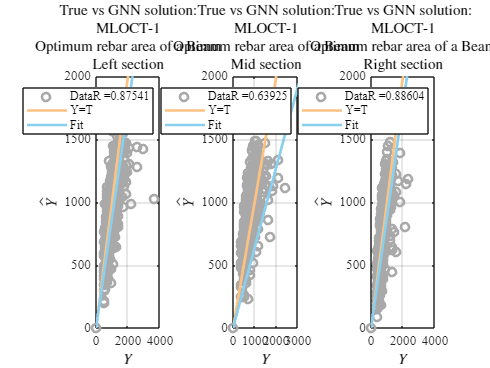

% Define pastel colors
pastel_gray = [0.663,0.663,0.663]; % #D3D3D3 for scatter points
pastel_green = [0.537,0.812,0.941]; % #B5EAD7 for fit line
pastel_orange = [0.992,0.761,0.506]; % #FDC281 for identity line

figure(9)
subplot(1,3,1)
plot([0;YAo1],[0;Ypvt1],'o', 'Color', pastel_gray,'LineWidth',2)
hold on
plot([0;YAo1],[0;YAo1],'-', 'Color', pastel_orange,'LineWidth',2)
hold on
plot([0;YAo1],[0;YPT1],'-', 'Color', pastel_green,'LineWidth',2)
hold on
legend(strcat('Data ','R = ',num2str(BT1(1))),'Y=T','Fit')
xlabel('$Y$',interpreter='latex')
ylabel('$\hat{Y}$',interpreter='latex')
title({strcat('True vs GNN ', ' solution:'),'MLOCT-5','Optimum rebar area of a Beam',...
    'Left section'},interpreter='latex') 
hold on
grid on
axis([[0 4000],[0 2000]])
set(gca, 'Fontname', 'Times New Roman','FontSize',10);


figure(9)
subplot(1,3,2)
plot([0;YAo2],[0;Ypvt2],'o', 'Color', pastel_gray,'LineWidth',2)
hold on
plot([0;YAo2],[0;YAo2],'-', 'Color', pastel_orange,'LineWidth',2)
hold on
plot([0;YAo2],[0;YPT2],'-', 'Color', pastel_green,'LineWidth',2)
hold on
legend(strcat('Data ','R = ',num2str(BT2(1))),'Y=T','Fit')
xlabel('$Y$',interpreter='latex')
ylabel('$\hat{Y}$',interpreter='latex')
title({strcat('True vs GNN ', ' solution:'),'MLOCT-5','Optimum rebar area of a Beam',...
    'Mid section'},interpreter='latex') 
hold on
grid on
axis([[0 3000],[0 2000]])
set(gca, 'Fontname', 'Times New Roman','FontSize',10);

figure(9)
subplot(1,3,3)
plot([0;YAo3],[0;Ypvt3],'o', 'Color', pastel_gray,'LineWidth',2)
hold on
plot([0;YAo3],[0;YAo3],'-', 'Color', pastel_orange,'LineWidth',2)
hold on
plot([0;YAo3],[0;YPT3],'-', 'Color', pastel_green,'LineWidth',2)
hold on
legend(strcat('Data ','R = ',num2str(BT3(1))),'Y=T','Fit')
xlabel('$Y$',interpreter='latex')
ylabel('$\hat{Y}$',interpreter='latex')
title({strcat('True vs GNN ', ' solution:'),'MLOCT-5','Optimum rebar area of a Beam',...
    'Right section'},interpreter='latex') 
hold on
grid on
axis([[0 4000],[0 2000]])
set(gca, 'Fontname', 'Times New Roman','FontSize',10);

## Model function

Define the model. The model takes as input a feature matrix `X` and an adjacency matrix `A` and outputs categorical predictions.

- The model uses a masked multihead self attention mechanism to aggregate features across the neighborhood of a node, that is, the set of nodes that are directly connected to the node. The mask, which is obtained from the adjacency matrix, is used to prevent *attention* between nodes that are not in the same neighborhood.

- The model uses ReLU nonlinearity, after each layers, as the activation function.

- To aid convergence, the model uses a skip connection between the graph attention layer and the convolutional layer.


function Y = model1FC2GAT1Conv1FC(parameters,X,A,numHeads)

    Z1 = X * parameters.Embedding.Weights + parameters.Embedding.b;

    weights1 = parameters.attn1.Weights;
    numHeadsAttention1 = numHeads.attn1;
    
    [Z2,~] = graphAttention(Z1,A,weights1,numHeadsAttention1,"cat");
    Z2  = relu(Z2);

    ANorm = normalizeAdjacency(A);
    Z3 = single(full(ANorm)) * Z2 * double(parameters.mult1.Weights);
    Z3  = relu(Z3) + Z2;

    Z4 = Z3 * parameters.Decoder.Weights + parameters.Decoder.b;
    
    Y = Z4;
end


## Model Loss Function

The `modelLoss` function takes as inputs the model parameters `parameters`, the feature matrix `X`, the adjacency matrix `adjacencyTrain`, the number of nodes per graph `numNodes`, the labels `T`, and the number of heads `numHeads`, and returns the gradients of the loss with respect to the model parameters, the corresponding loss, and the model predictions.

function [loss,gradients] = modelLoss1fc2Gat1Conv1fc(parameters,X,A,T,numHeads)
    
    Y = model1FC2GAT1Conv1FC(parameters,X,A,numHeads);
    
    loss = mse(Y,T,DataFormat="BC");
    gradients = dlgradient(loss, parameters);

end

## Preprocess Mini-Batch Function

These functions process the labeled data and features to generate an array of one single column. It pads the node features.


function [adjacency,features,labels] = preprocessData(adjacencyData,coulombData,atomData)

    [adjacency, features] = preprocessPredictors(adjacencyData,coulombData);
    labels = [];
    
    % Convert labels to categorical.
    for i = 1:size(adjacencyData,3)
        % Extract and append unpadded data.
        T = atomData(i,:);
        labels = [labels; T'];
    end
    
end

function [adjacency,features] = preprocessPredictors(adjacencyData,coulombData)

    adjacency = sparse([]);
    features = [];
    
    for i = 1:size(adjacencyData, 3)
        % Extract unpadded data.
        numNodes = find(any(adjacencyData(:,:,i)),1,"last");
        
        A = adjacencyData(1:numNodes,1:numNodes,i);
        X = coulombData(1:numNodes,1:numNodes,i);
    
        % Extract feature vector from diagonal of Coulomb matrix.
        X = diag(X);
    
        % Append extracted data.
        adjacency = blkdiag(adjacency,A);
        features = [features; X];
    end

end


## Model Predictions Function

The `modelPredictions` function takes as inputs the model parameters `parameters`, the datastore object `ds` holding the features and adjacency data, and the number of heads `numHeads`, and returns the model predictions by iterating over mini-batches of data and preprocessing each mini-batch using the `preprocessMiniBatch` function.

## Attention Function

The `graphAttention` function computes node features using masked multihead self-attention.

Given input node features $Z_l$ of dimension $N \times F$, where $N$ is the number of nodes and $F$ is the number of input features, at layer $l$, the attention function computes the output node features $Z_{l+1}$ of dimension $N \times KF'$, where $KF'$ is the number of output features of the layer, as follows:

- Using $K$ independent heads, it computes linear transformations $H^k$, for $k = 1, ..., K$, of the input features using weight matrices $W_l^k$ of dimensions $F \times F'$. That is, $H^k = Z_lW_l^k$.

- It uses an attention mechanism to compute the scalar attention coefficients $\varepsilon^k_{nm} = a^k(h^k_n,h^k_m)$ for all node pairs $(n,m)$, where $h_n^k$ is a vector of dimension $1 \times F'$ corresponding to the *n*th row of matrix $H^k$. The attention coefficient $\varepsilon^k_{nm}$ represents the importance of node $m$ to node $n$ at head $k$. The attention mechanism $a$ can be a dot product operation of features $h_n$ and $h_m$, or a neural network. This example follows the approach in [1], where features $h_n$ and $h_m$ are concatenated and the attention mechanism is a single-layer neural network with weights array $\theta_l^k$, consisting of $2F'$ elements, that is shared across all nodes, followed by leaky-ReLU nonlinearity.

- To prevent attention between nodes that are not directly connected, the GAT implements masked attention by using the graph structure, defined by the adjacency matrix, to compute a mask such that the masked attention coefficients $\bar\varepsilon_{nm} = -\inf$ for all $m \notin \mathcal{N}_n$, where $\mathcal{N}_n$ is the neighborhood of node $n$, including $n$, and $\bar\varepsilon_{nm} = \varepsilon_{nm}$ for all $m \in \mathcal{N}_n$.

- Attention scores are computed by normalizing the masked attention coefficients using a softmax operation. That is, the attention score $\alpha_{nm}^k = \frac{\exp(\bar\varepsilon_{nm}^k)}{\sum_{j\in\mathcal{N}_n}\exp(\bar\varepsilon_{nj}^k)}$.

- The attention scores are then used to obtain the output features of the layer as a linear combination of transformations $H^k$. That is, given a $N \times N$matrix of attention scores $\mathbf{\alpha}^k$ computed at head $k$, output features $Z_{l+1}^k$ from attention head $k$ are obtained as $Z_{l+1}^k = \mathbf{\alpha}^kH^k$.

- The output features from each attention head are aggregated, either by concatenation, that is, $Z_{l+1} = [Z_{l+1}^1, ..., Z_{l+1}^K]$, or by averaging, that is $Z_{l+1}= \frac{1}{K}\sum_{k=1}^KZ_{l+1}^k$, to give the output features of the layer. 

The `graphAttention` function takes as inputs the feature matrix `inputFeatures`, adjacency matrix `adjacency`, learnable parameters `weights`, the number of heads `numHeads`, and aggregation method for the multiple attention heads `aggregation`, and computes and returns features using masked multihead self attention.

The function splits the learnable parameters into multiple heads, and for each attention head, it:

- Computes a linear transformation of the input features.

- Computes attention coefficients using linearly transformed features.

- Masks attention coefficients.

- Normalizes masked attention coefficients.

- Normalizes linearly transformed features using normalized masked attention coefficients.

Finally, it aggregates the output features of different attention heads.


function [outputFeatures,normAttentionCoeff] = graphAttention(inputFeatures,adjacency,weights,numHeads,aggregation)

% Split weights with respect to the number of heads and reshape the matrix to a 3-D array
szFeatureMaps = size(weights.linearWeights);
numOutputFeatureMapsPerHead = szFeatureMaps(2)/numHeads;
linearWeights = reshape(weights.linearWeights,[szFeatureMaps(1), numOutputFeatureMapsPerHead, numHeads]);
attentionWeights = reshape(weights.attentionWeights,[numOutputFeatureMapsPerHead, 2, numHeads]);

% Compute linear transformations of input features
value = pagemtimes(inputFeatures,linearWeights);

% Compute attention coefficients
query = pagemtimes(value, attentionWeights(:, 1, :));
key = pagemtimes(value, attentionWeights(:, 2, :));

attentionCoefficients = query + permute(key,[2, 1, 3]);
attentionCoefficients = leakyrelu(attentionCoefficients,0.2);

% Compute masked attention coefficients
mask = -10e9 * (1 - adjacency);
attentionCoefficients = attentionCoefficients + mask;

% Compute normalized masked attention coefficients
normAttentionCoeff = softmax(attentionCoefficients,DataFormat = "BCU");

% Normalize features using normalized masked attention coefficients
headOutputFeatures = pagemtimes(normAttentionCoeff,value);

% Aggregate features from multiple heads
if strcmp(aggregation, "cat")
    outputFeatures = headOutputFeatures(:,:);
else
    outputFeatures =  mean(headOutputFeatures,3);
end

end

function weights = initializeGlorot(sz,numOut,numIn,className)

arguments
    sz
    numOut
    numIn
    className = 'single'
end

Z = 2*rand(sz,className) - 1;
bound = sqrt(6 / (numIn + numOut));

weights = bound * Z;
weights = dlarray(weights);

end

function parameter = initializeZeros(sz,className)

arguments
    sz
    className = 'single'
end

parameter = zeros(sz,className);
parameter = dlarray(parameter);

end

function ANorm = normalizeAdjacency(A)

% Add self connections to adjacency matrix.
A = A + speye(size(A));

% Compute inverse square root of degree.
degree = sum(A, 2);
degreeInvSqrt = sparse(sqrt(1./degree));

% Normalize adjacency matrix.
ANorm = diag(degreeInvSqrt) * A * diag(degreeInvSqrt);

end

## Data partition


function varargout = trainingPartitions(numObservations,splits)
%TRAININGPARTITONS Random indices for splitting training data
%   [idx1,...,idxN] = trainingPartitions(numObservations,splits) returns
%   random vectors of indices to help split a data set with the specified
%   number of observations, where SPLITS is a vector of length N of
%   partition sizes that sum to one.
%
%   % Example: Get indices for 50%-50% training-test split of 500
%   % observations.
%   [idxTrain,idxTest] = trainingPartitions(500,[0.5 0.5])
%
%   % Example: Get indices for 80%-10%-10% training, validation, test split
%   % of 500 observations. 
%   [idxTrain,idxValidation,idxTest] = trainingPartitions(500,[0.8 0.1 0.1])
%{
arguments
    numObservations (1,1) {mustBePositive}
    splits {mustBeVector,mustBeInRange(splits,0,1,"exclusive"),mustSumToOne}
end
%}
numPartitions = numel(splits);
varargout = cell(1,numPartitions);

idx = randperm(numObservations);

idxEnd = 0;

for i = 1:numPartitions-1
    idxStart = idxEnd + 1;
    idxEnd = idxStart + floor(splits(i)*numObservations) - 1;

    varargout{i} = idx(idxStart:idxEnd);
end

% Last partition.
varargout{end} = idx(idxEnd+1:end);

end

function mustSumToOne(v)
% Validate that value sums to one.

if sum(v,"all") ~= 1
    error("Value must sum to one.")
end

end

function [B]=MLR2(D,inter)
    
    n=length(D(:,1));
    p=length(D(1,:));
    if inter==1
        X=[ones(n,1),D(:,1:p-1)];
    elseif inter==0
        X=[D(:,1:p-1)];
    end
    Y=D(:,p);
    
    B=inv(X'*X)*X'*Y;
end

## References